## 图形和矩阵

### 示例一——bucky

图形是一组相互之间具有指定连接或边的节点。图形有许多形状和大小。Buckminster Fuller 多面穹顶（也就是足球或碳 60 分子的形状）的连接图就是这样一个示例。

在 MATLAB® 中，可以使用 `bucky` 函数来生成多面穹顶的图形。

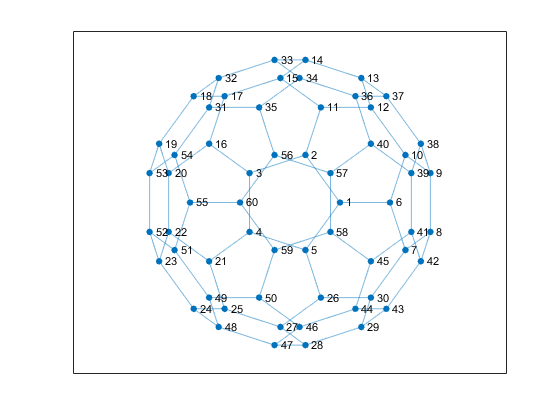

figure
[B,V] = bucky;
G = graph(B);
p = plot(G);
axis equal
p.XData = V(:,1);
p.YData = V(:,2);

`bucky` 函数可用于创建图形，因为它返回邻接矩阵。邻接矩阵是一种表示图形中的节点和边的方式。

要构造图形的邻接矩阵，节点应按 1 至 N 进行编号。如果节点 i 连接至节点 j，则 N×N 矩阵的每个元素 (i,j) 都设置为 1，否则设置为 0。因此，对于无向图，邻接矩阵是对称的，但有向图不必如此。

### 示例二——图示邻接矩阵

简单的图形及其关联的邻接矩阵

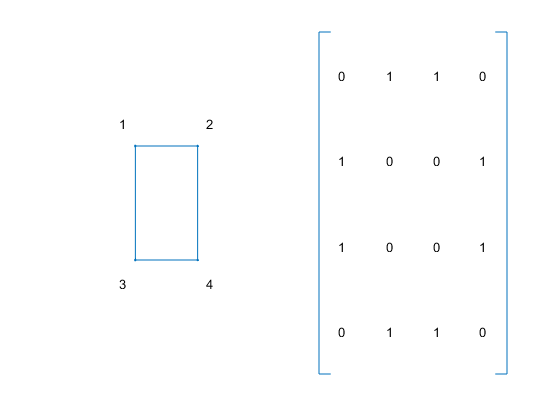

% Define a matrix A.
A = [0 1 1 0 ; 1 0 0 1 ; 1 0 0 1 ; 0 1 1 0];

% Draw a picture showing the connected nodes.
figure
subplot(1,2,1);
gplot(A,[0 1;1 1;0 0;1 0],'.-');
text([-0.2, 1.2 -0.2, 1.2],[1.2, 1.2, -.2, -.2],('1234')', ...
   'HorizontalAlignment','center')
axis([-1 2 -1 2],'off')

% Draw a picture showing the adjacency matrix.
subplot(1,2,2);
xtemp = repmat(1:4,1,4);
ytemp = reshape(repmat(1:4,4,1),16,1)';
text(xtemp-.5,ytemp-.5,char('0'+A(:)),'HorizontalAlignment','center');
line([.25 0 0 .25 NaN 3.75 4 4 3.75],[0 0 4 4 NaN 0 0 4 4])
axis off tight

### 稀疏矩阵

稀疏矩阵特别有助于表示非常大的图形。这是因为每个节点通常只会连接到少数几个其他节点。因此，对于大型图形，邻接矩阵中非零项的密度通常比较小。布基球邻接矩阵就是一个很好的示例，因为它是一个 60×60 的对称稀疏矩阵，仅包含 180 个非零元素。此矩阵的密度仅为 5%。

由于邻接矩阵定义图形，因此您可以使用邻接矩阵中的条目子集来绘制布基球的一部分。

### `adjacency`

使用 `adjacency` 函数为图形创建新的邻接矩阵。通过对该邻接矩阵进行索引创建一个新的较小图形，以显示布基球的一个半球中的节点。

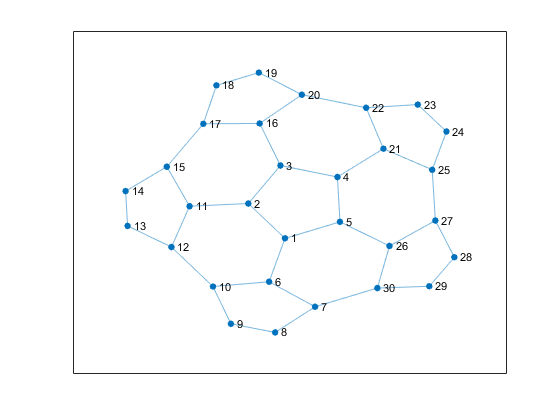

figure
A = adjacency(G);
H = graph(A(1:30,1:30));
h = plot(H);

### `spy`

要实现此半球的邻接矩阵可视化，请使用 `spy` 函数对邻接矩阵中的非零元素的轮廓进行绘图。

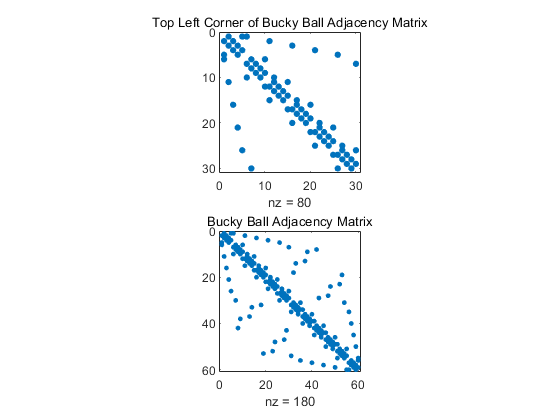

figure
subplot(211)
spy(A(1:30,1:30))
title('Top Left Corner of Bucky Ball Adjacency Matrix')
subplot(212)
spy(A)
title('Bucky Ball Adjacency Matrix')

## 修改现有图的节点和边

### **添加节点**

s = [1 1 1 2];
t = [2 3 4 3];
G = graph(s,t)

G =   graph - 属性:

    Edges: [4×1 table]
    Nodes: [4×0 table]


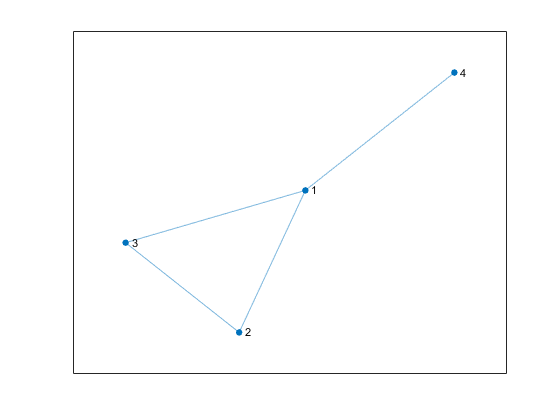

figure
plot(G)

G.Edges

ans = 4×1 table
    EndNodes
    ________

     1    2 
     1    3 
     1    4 
     2    3 
